Audio Steganography Task 

Read and plot the Message audio file (audio1)

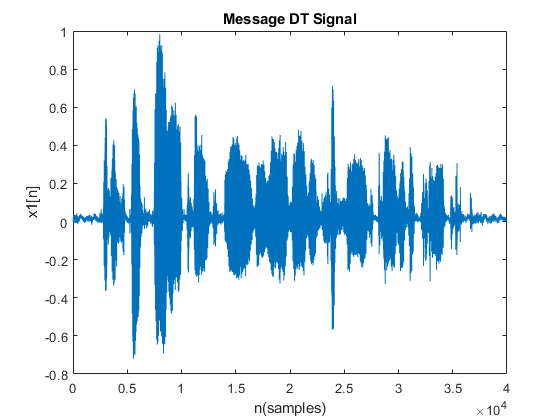

[message, messageFs] = audioread("audio1.wav");
plot(message)
xlabel("n(samples)")
ylabel("x1[n]")
title("Message DT Signal")

Read and plot the Carrier audio file (audio2)

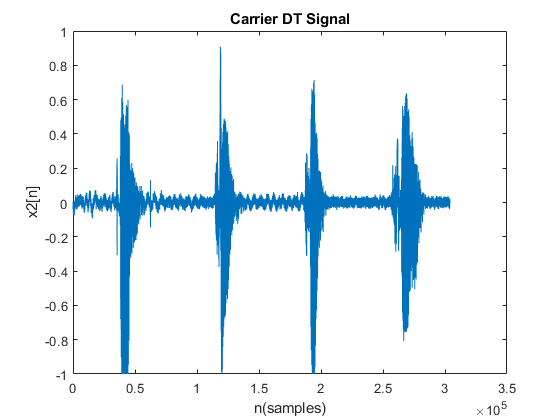

[carrier, carrierFs] = audioread("audio2.wav");
plot(carrier)
xlabel("n(samples)")
ylabel("x2[n]")
title("Carrier DT Signal")

Resamping the audio files to a new sampling rate newFs to satisfy the sampling theorem when moving the message to a higher frequency band

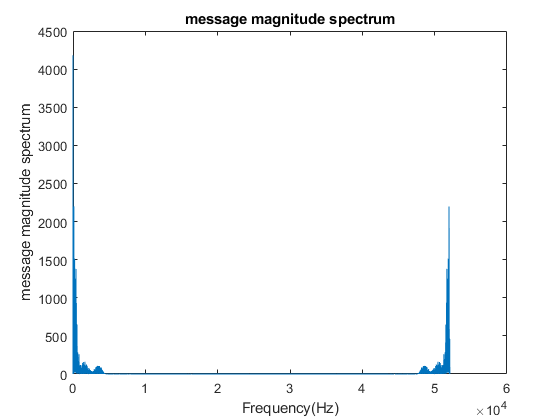

newFs = 52100;

[p, q] = rat(newFs/messageFs);
message = resample(message, p, q);
% get the message number of samples after resampling and the scales to use for plotting
nMessageSamples = length(message);
messageFftFrequencyScale = (newFs/nMessageSamples) * (0:nMessageSamples - 1);
messageTimeScale = (1/newFs) * (0:nMessageSamples - 1);
% plot the message in frequency domain
plot(messageFftFrequencyScale, abs(fft(message)))
xlabel("Frequency(Hz)")
ylabel("message magnitude spectrum")
title("message magnitude spectrum")

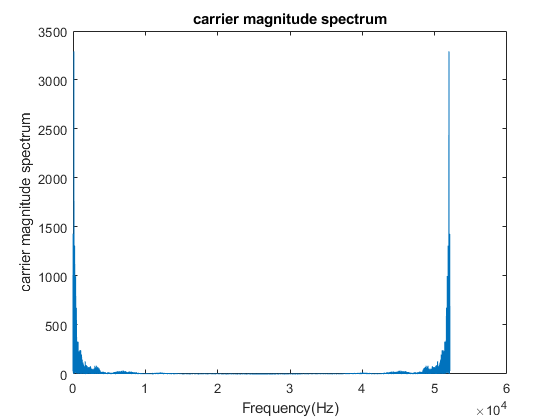


[p, q] = rat(newFs/carrierFs);
carrier = resample(carrier, p, q);
% get the carrier number of samples after resampling and the scales to use for plotting
nCarrierSamples = length(carrier);
carrierFftFrequencyScale = (newFs/nCarrierSamples) * (0:nCarrierSamples - 1);
carrierTimeScale = (1/newFs) * (0:nCarrierSamples - 1);
% plot the carrier in frequency domain
plot(carrierFftFrequencyScale, abs(fft(carrier)))
xlabel("Frequency(Hz)")
ylabel("carrier magnitude spectrum")
title("carrier magnitude spectrum")

Preparing the parameters to be used for hiding the message into the carrier

attenuationFactor = 0.5;
shiftingFrequency = 22500;

shiftingCosineMessage = cos(2 * pi * shiftingFrequency * messageTimeScale)';

Hiding the message into the carrier using the equation to shift the message frequency band to the higher inaudible frequency components where they don' t overlap with the carrier frequency components and attenuating them

carrierHidden = zeros(1, nCarrierSamples);
carrierHidden = carrierHidden + carrier';
shiftedMessage = attenuationFactor * (message .* shiftingCosineMessage);
carrierHidden(1:nMessageSamples) = carrierHidden(1:nMessageSamples) + shiftedMessage';

audiowrite('hidden.wav', carrierHidden, newFs);

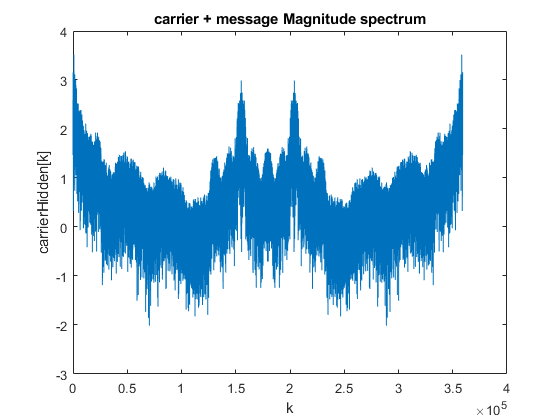

% sound(carrierHidden, newFs)

carrierHiddenFft = fft(carrierHidden);
% plot the magnitude spectrum of the fft of the carrier holding the message 
plot(log10(abs(carrierHiddenFft)))
xlabel("k")
ylabel("carrierHidden[k]")
title("carrier + message Magnitude spectrum")

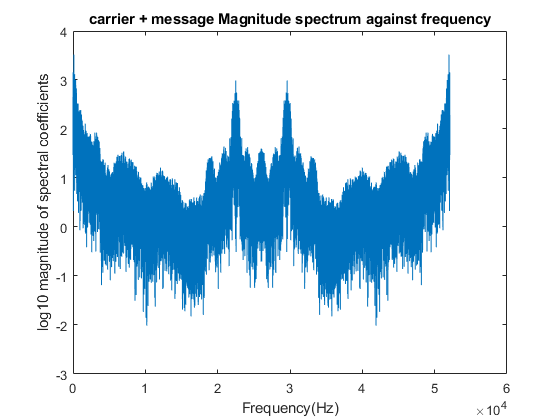

% plot the magnitude spectrum of the fft with the frequency scale
plot(carrierFftFrequencyScale, (log10(abs(carrierHiddenFft))))
xlabel("Frequency(Hz)")
ylabel("log10 magnitude of spectral coefficients")
title("carrier + message Magnitude spectrum against frequency")

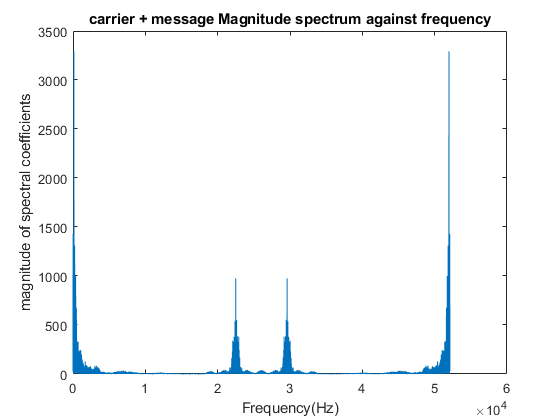

% plot the magnitude spectrum of the fft with the frequency scale
plot(carrierFftFrequencyScale, abs(carrierHiddenFft))
xlabel("Frequency(Hz)")
ylabel("magnitude of spectral coefficients")
title("carrier + message Magnitude spectrum against frequency")

Retrieving the hidden message

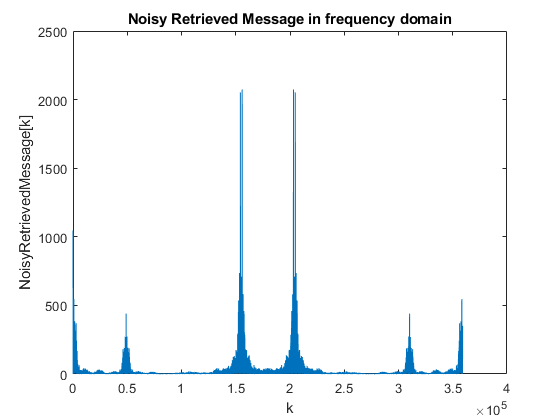

shiftingCosineCarrier = cos(2 * pi * shiftingFrequency * carrierTimeScale);

NoisyRetrievedMessage = carrierHidden .* shiftingCosineCarrier;

%plot the fft of the noisy message
NoisyRetrievedMessageFft = fft(NoisyRetrievedMessage);
plot(abs(NoisyRetrievedMessageFft))
xlabel("k")
ylabel("NoisyRetrievedMessage[k]")
title("Noisy Retrieved Message in frequency domain")

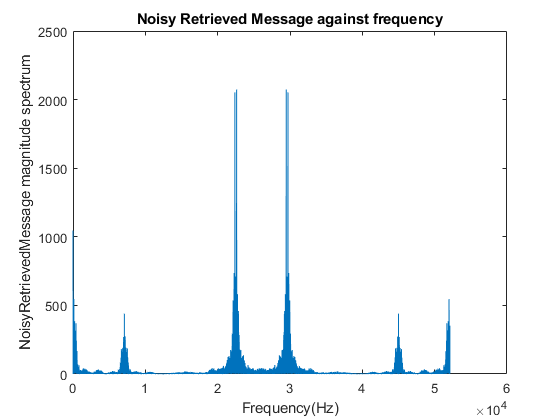


NoisyRetrievedMessageFft = fft(NoisyRetrievedMessage);
plot(carrierFftFrequencyScale, abs(NoisyRetrievedMessageFft))
xlabel("Frequency(Hz)")
ylabel("NoisyRetrievedMessage magnitude spectrum")
title("Noisy Retrieved Message against frequency")

Removing the noise in Frequency domain  to restore the original message 

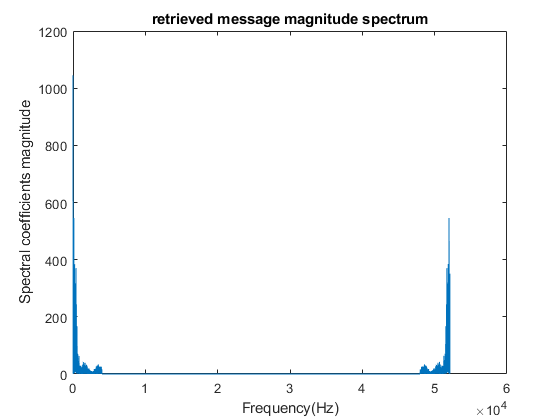

% filter from freq 0 Hz to 4000 Hz from Right hand side & its mirrored part on 
% Left hand side since the original sampling rate of the message signal was 8000 Hz
% specify the region in terms of Bin frequencies k
kStart = 27573;
kEnd = 330877;

retrievedMessageFft = NoisyRetrievedMessageFft;
retrievedMessageFft(kStart: kEnd) = retrievedMessageFft(kStart: kEnd) * 0;

retrievedMessage = ifft(retrievedMessageFft);
plot(carrierFftFrequencyScale, abs(retrievedMessageFft))
xlabel("Frequency(Hz)")
ylabel("Spectral coefficients magnitude")
title("retrieved message magnitude spectrum")


sound(abs(retrievedMessage), newFs)

% Remove the last extra two seconds from the audio file to restore the length of the old
% audio file
retrievedMessage = retrievedMessage(1: nMessageSamples);
audiowrite('retrieved.wav', abs(retrievedMessage) ,newFs)
